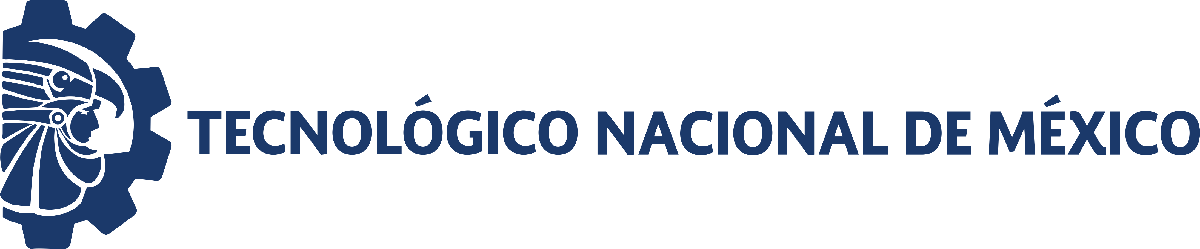                                 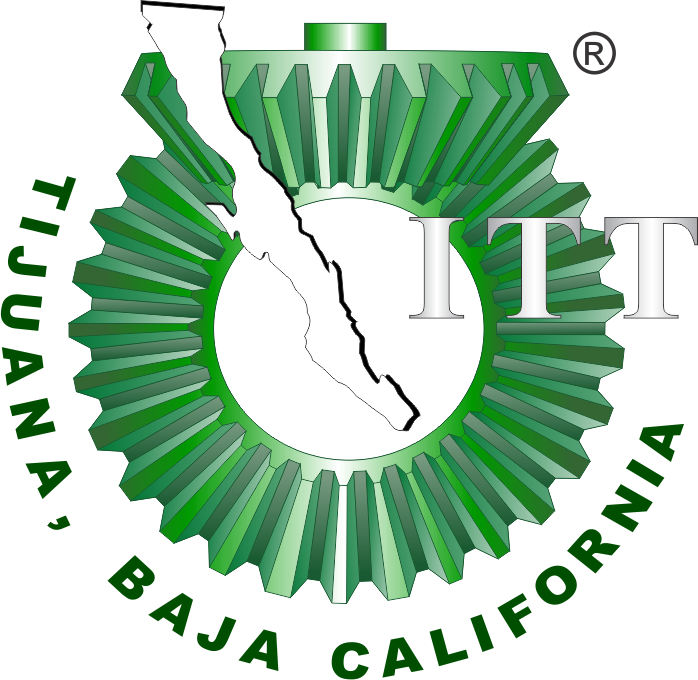

# Práctica 3: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

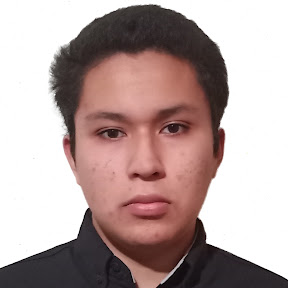

Nombre del alumno: **Ramírez Zepeda Alejandro**

Número de control: **22211765**

Correo institucional: **L22211765@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema3_1';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Grafica lazo abierto

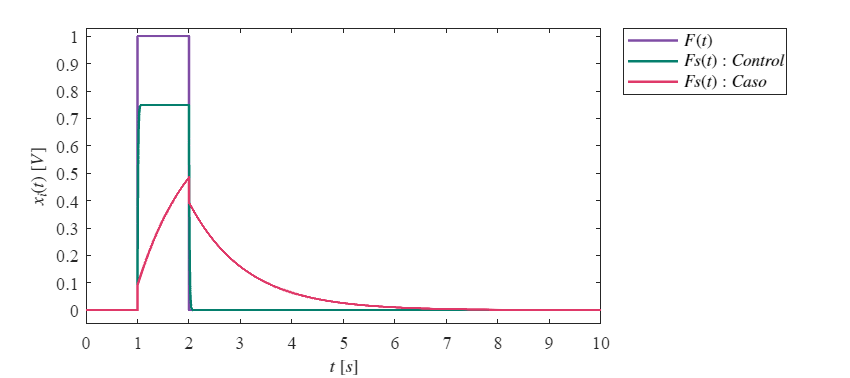

signal1 = 'Graficas lazos abierto';
x = sim(file,parameters);
%writematrix(x.F(t),'signal.xlsx')
plotsignals1(x.t,x.F,x.Fs1,x.Fs2,signal1)

## Grafica lazo cerrado

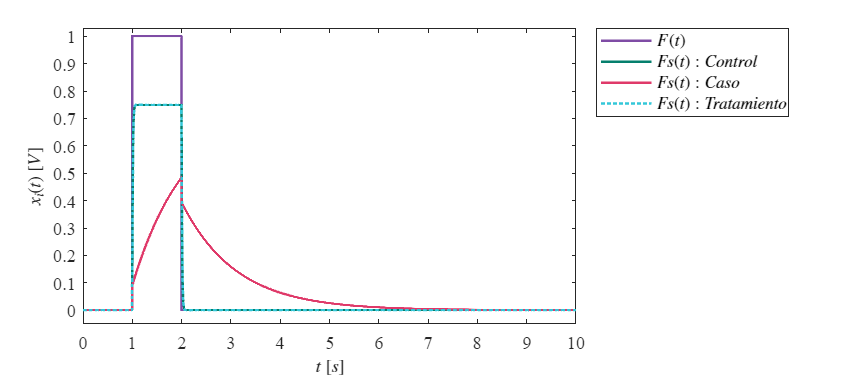

signal2 = 'Graficas lazo cerrado';
x1 = sim(file,parameters);
plotsignals2(x1.t,x1.F,x1.Fs1,x1.Fs2,x1.Fs3,signal2)

## Función: Respuesta a las señales 1

function plotsignals1(t,F,Fs1,Fs2,signal1)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors =    [127,76,165;
                5,127,109;
                223,57,105;
                51,199,216;
                255,141,20;
                123,45,67]/255;
    colororder(mycolors)

   p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',...
       'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));

    L = legend('$F(t)$','$Fs(t): Control$','$Fs(t): Caso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10);
    ylim([-0.05,1.03]); yticks(0:0.1:1);

    exportgraphics(gcf,[signal1, '.pdf'],'ContentType','vector')
    exportgraphics(gcf,[signal1, '.png'],'ContentType','vector')
    
end

## Función: Respuesta a las señales 2

function plotsignals2(t,F,Fs1,Fs2,Fs3,signal2)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    mycolors = [127,76,165;
                5,127,109;
                223,57,105;
                51,199,216]/255;
    colororder(mycolors)

    p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',t,Fs3,':',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));

    L = legend('$F(t)$','$Fs(t): Control$','$Fs(t): Caso$','$Fs(t): Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)


    xlim([0,10]); xticks(0:1:10);
    ylim([-0.05,1.03]); yticks(0:0.1:1);

    exportgraphics(gcf,[signal2, '.pdf'],'ContentType','vector')
    exportgraphics(gcf,[signal2, '.png'],'ContentType','vector')

end
